% clear;clc;close all;
set(0, 'defaultlinelinewidth', 1)
set(0, 'defaultaxeslinewidth', 2);
set(0, 'defaultaxesfontsize', 28);
set(0, 'defaulttextfontsize', 28);
set(0, 'DefaultLineMarkerSize', 10);
set(0, 'Defaultaxesfontname', 'Times New Roman');

plot(x, y);

title('随机步长 = 0.001')
xlabel('$t$','interpreter','latex');
ylabel('$f$','interpreter','latex');
set(gcf,'unit','centimeters','position',[20 20 20 20])

saveas(gcf,'f1e-3L','epsc')

histogram(y, 20, 'Normalization', 'probability');

title('随机步长 = 0.001')
xlabel('$f$','interpreter','latex');
ylabel('概率密度');
set(gcf,'unit','centimeters','position',[20 20 20 20])
view(90,-90)
saveas(gcf,'p1e-3L','epsc')

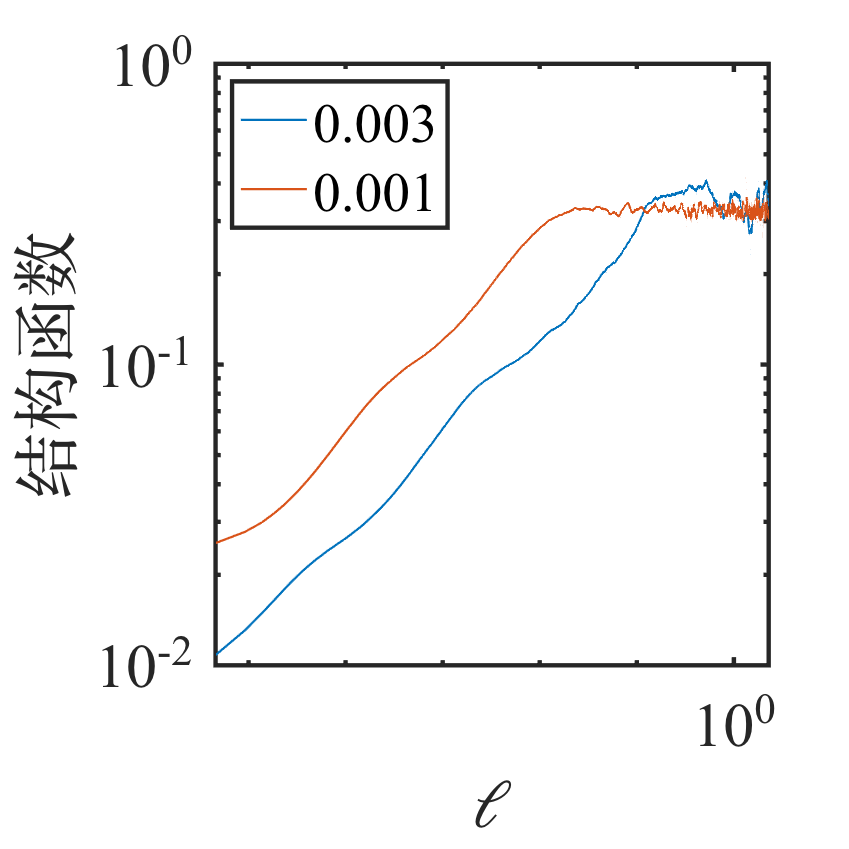


loglog(x1(1:floor((end-1)/2)), stru1(1:floor((end)/2)));
hold on;
loglog(x(1:floor((end-1)/2)), stru(1:floor((end)/2)));
hold off;
legend('0.003', '0.001', 'Location','northwest')
xlabel('$\ell$','interpreter','latex');
ylabel('结构函数');
set(gcf,'unit','centimeters','position',[20 20 20 20])
saveas(gcf,'L1e-3L','epsc')